clear;clc;

- **实验计算**

%%%%%%%%%实验条件%%%%%%%%%
k=0.6:0.001:1.4;%频率，单位取GHz
Z0=50;
%题（1）
Rl1=100;
Rl2=200;
Rl3=400;
%题（2）
Rl=200;
%%%%%%%%%题（1）%%%%%%%%%
%1.计算匹配支节阻抗Z_01
Z01=sqrt(Z0*Rl1);
Z02=sqrt(Z0*Rl2);
Z03=sqrt(Z0*Rl3);
disp('单节匹配且Rl=200时，Z_01=');

单节匹配且Rl=200时，Z_01=


disp(Z02);

   100



%2.计算输入阻抗
Zin1=Z01.*(Rl1.*cos(pi/2.*k)+1i.*Z01.*sin(pi/2.*k))./(Z01.*cos(pi/2.*k)+1i.*Rl1.*sin(pi/2.*k));
Zin2=Z02.*(Rl2.*cos(pi/2.*k)+1i.*Z02.*sin(pi/2.*k))./(Z02.*cos(pi/2.*k)+1i.*Rl2.*sin(pi/2.*k));
Zin3=Z03.*(Rl3.*cos(pi/2.*k)+1i.*Z03.*sin(pi/2.*k))./(Z03.*cos(pi/2.*k)+1i.*Rl3.*sin(pi/2.*k));
%3.计算反射系数及其模值（模值已取20log）
gamma_1=(Zin1-Z0)./(Zin1+Z0);
abs_gamma_1=20*log10(abs(gamma_1));
gamma_2=(Zin2-Z0)./(Zin2+Z0);
abs_gamma_2=20*log10(abs(gamma_2));
gamma_3=(Zin3-Z0)./(Zin3+Z0);
abs_gamma_3=20*log10(abs(gamma_3));
%%%%%%%%%题（2）%%%%%%%%%
%1.设置中间阻抗(即接入了Z_01，但未接入Z_02处的输入阻抗)
Z_middle1=sqrt(Z0*Rl);% 取几何平均
Z_middle2=(Z0+Rl)/2;% 取代数平均
%2.取几何平均时的情况
Z01_1=sqrt(Z_middle1*Rl);% 第一节
Zin11=Z01_1.*(Rl.*cos(pi/2.*k)+1i.*Z01_1.*sin(pi/2.*k))./(Z01_1.*cos(pi/2.*k)+1i.*Rl.*sin(pi/2.*k));
Z02_1=sqrt(Z0*Z_middle1);% 第二节
Zin12=Z02_1.*(Zin11.*cos(pi/2.*k)+1i.*Z02_1.*sin(pi/2.*k))./(Z02_1.*cos(pi/2.*k)+1i.*Zin11.*sin(pi/2.*k));
gamma_4=(Zin12-Z0)./(Zin12+Z0);% 反射系数
abs_gamma_4=20*log10(abs(gamma_4));
disp('几何平均时Z_01=')

几何平均时Z_01=


disp(Z01_1);

  141.4214



disp('几何平均时Z_02=')

几何平均时Z_02=


disp(Z02_1);

   70.7107



%3.取代数平均时的情况
Z01_2=sqrt(Z_middle2*Rl);
Z02_2=sqrt(Z0*Z_middle2);
Zin21=Z01_2.*(Rl.*cos(pi/2.*k)+1i.*Z01_2.*sin(pi/2.*k))./(Z01_2.*cos(pi/2.*k)+1i.*Rl.*sin(pi/2.*k));
Zin22=Z02_2.*(Zin21.*cos(pi/2.*k)+1i.*Z02_2.*sin(pi/2.*k))./(Z02_2.*cos(pi/2.*k)+1i.*Zin21.*sin(pi/2.*k));
gamma_5=(Zin22-Z0)./(Zin22+Z0);
abs_gamma_5=20*log10(abs(gamma_5));
disp('代数平均时Z_01=')

代数平均时Z_01=


disp(Z01_2);

  158.1139



disp('代数平均时Z_02=')

代数平均时Z_02=


disp(Z02_2);

   79.0569



- **绘制图像**

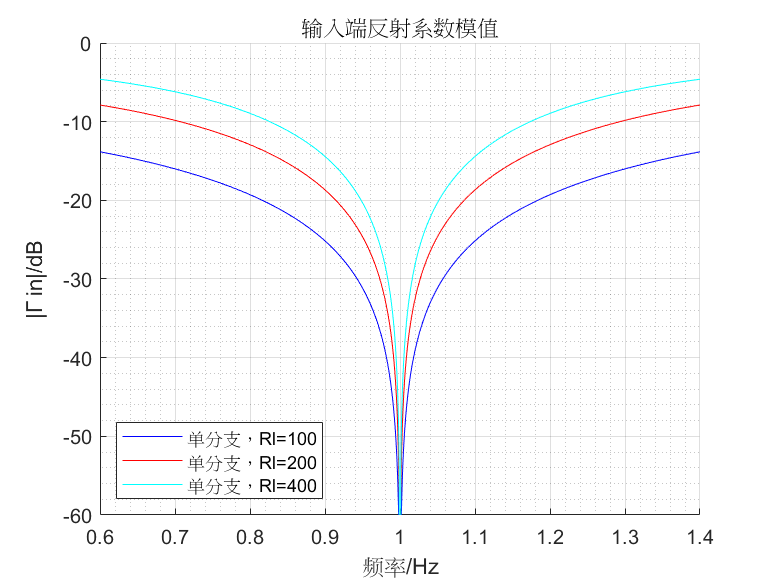

%%%%%%%%%题（1）%%%%%%%%%
figure(1);
hold on;
plot(k,abs_gamma_1,'b');
plot(k,abs_gamma_2,'r');
plot(k,abs_gamma_3,'c');
%%%%%%%%%%%%%%%%%%%
title('输入端反射系数模值');
axis([0.6 1.4 -60 0]);
lgd=legend('单分支，Rl=100','单分支，Rl=200','单分支，Rl=400');
lgd.Location = 'southwest';
xlabel('频率/Hz');
ylabel('|Γ_ in|/dB');
ylim([-60 0]);
grid on; grid minor;

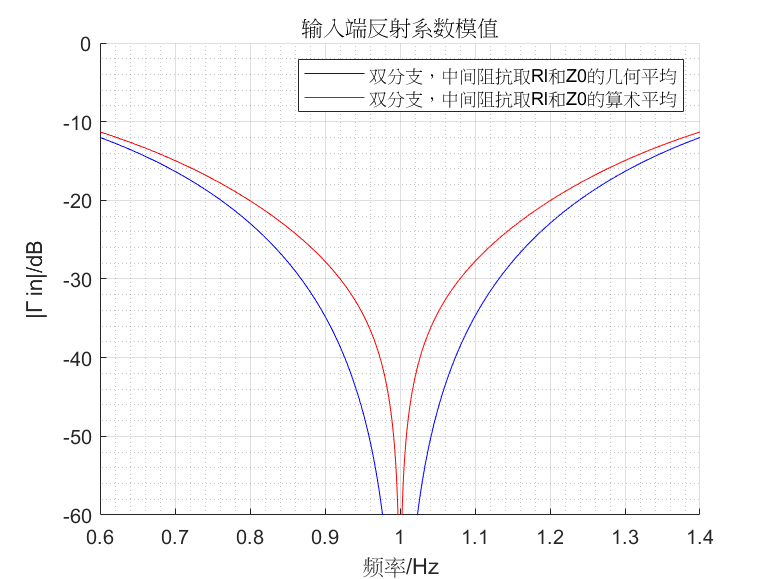


%%%%%%%%%题（2）-图1%%%%%%%%%
figure(2);
hold on;
plot(k,abs_gamma_4,'b');
plot(k,abs_gamma_5,'r');
%%%%%%%%%%%%%%%%%%%
title('输入端反射系数模值');
axis([0.6 1.4 -60 0]);
lgd=legend('双分支，中间阻抗取Rl和Z0的几何平均','双分支，中间阻抗取Rl和Z0的算术平均');
lgd.Location = 'northeast';
xlabel('频率/Hz');
ylabel('|Γ_ in|/dB');
ylim([-60 0]);
grid on; grid minor;

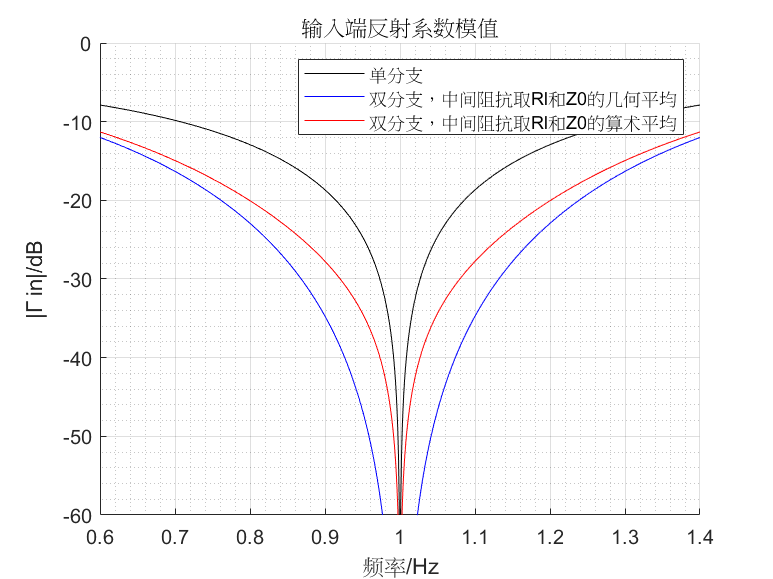


%%%%%%%%%题（2）-图2%%%%%%%%%
figure(3);
hold on
plot(k,abs_gamma_2,'k');
plot(k,abs_gamma_4,'b');
plot(k,abs_gamma_5,'r');
%%%%%%%%%%%%%%%%%%%
title('输入端反射系数模值');
axis([0.6 1.4 -60 0]);
lgd=legend('单分支','双分支，中间阻抗取Rl和Z0的几何平均','双分支，中间阻抗取Rl和Z0的算术平均');
lgd.Location = 'northeast';
xlabel('频率/Hz');
ylabel('|Γ_ in|/dB');
ylim([-60 0]);
grid on; grid minor;

补充内容：

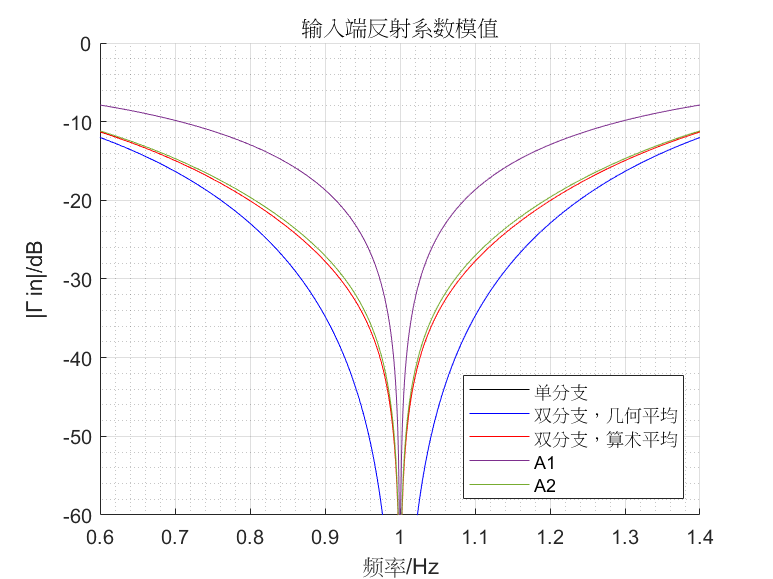

%%%%%%%%实验计算%%%%%%%%
%1.Z01取Rl和Z0的几何平均的情况
Z01_3=sqrt(Z0*Rl);
R_middle3=Z01_3*Z01_3/Rl;
Z02_3=sqrt(Z0*R_middle3);
Zin1_3=Z01_3.*(Rl.*cos(pi/2.*k)+1i.*Z01_3.*sin(pi/2.*k))./(Z01_3.*cos(pi/2.*k)+1i.*Rl.*sin(pi/2.*k));
Zin2_3=Z02_3.*(Zin1_3.*cos(pi/2.*k)+1i.*Z02_3.*sin(pi/2.*k))./(Z02_3.*cos(pi/2.*k)+1i.*Zin1_3.*sin(pi/2.*k));
gamma6=(Zin2_3-Z0)./(Zin2_3+Z0);
abs_gamma6=20*log10(abs(gamma6));

%2.Z01取Rl和Z0的算术平均的情况
Z01_4=(Z0+Rl)/2;
R_middle4=Z01_4*Z01_4/Rl;
Z02_4=sqrt(Z0*R_middle4);
Zin1_4=Z01_4.*(Rl.*cos(pi/2.*k)+1i.*Z01_4.*sin(pi/2.*k))./(Z01_4.*cos(pi/2.*k)+1i.*Rl.*sin(pi/2.*k));
Zin2_4=Z02_4.*(Zin1_4.*cos(pi/2.*k)+1i.*Z02_4.*sin(pi/2.*k))./(Z02_4.*cos(pi/2.*k)+1i.*Zin1_4.*sin(pi/2.*k));
%disp(Zin22(400:402));
gamma7=(Zin2_4-Z0)./(Zin2_4+Z0);
abs_gamma7=20*log10(abs(gamma7));
%%%%%%%%绘制图像%%%%%%%%%
figure(4);
hold on;
plot(k,abs_gamma_2,'k');
plot(k,abs_gamma_4,'b');
plot(k,abs_gamma_5,'r');
plot(k,abs_gamma6);
plot(k,abs_gamma7);
%%%%%%%%%%%%%%%%%%%
title('输入端反射系数模值');
axis([0.6 1.4 -60 0]);
lgd=legend('单分支','双分支，几何平均','双分支，算术平均','A1','A2');
lgd.Location = 'southeast';
xlabel('频率/Hz');
ylabel('|Γ_ in|/dB');
ylim([-60 0]);
grid on; grid minor;

- 函数add_serline，增加一定长度的传输线。

function Zin = add_serline(Z0, theta, ZL)
    Zin=Z0.*(ZL.*cos(theta)+Z0.*sin(theta)*1i)./(Z0.*cos(theta)+ZL.*sin(theta)*1i);
end